T=[29.5 31.1 33.5 36 38.3 41.3 43.9 45.6 48.4 50.8 53.3 55.8 58.0 62.8 64.4 69.1 79.5 85.5 93.6 100.0 112.8 124.3 139.4 162.7 203.7 220.4 236.5 252.3 303.6 342.4 374.8];
V=(10^(-3)).*[0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.45 0.5 0.55 0.6 0.65 0.75 0.8 0.9 1.2 1.4 1.6 1.8 2.2 2.6 3 4 6 7 8 9 1.4 1.8 2.2];
logT=log10(T);
logV=log10(V);
T=T+273.15;
Terr=0.1*ones(31,1)

Terr =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


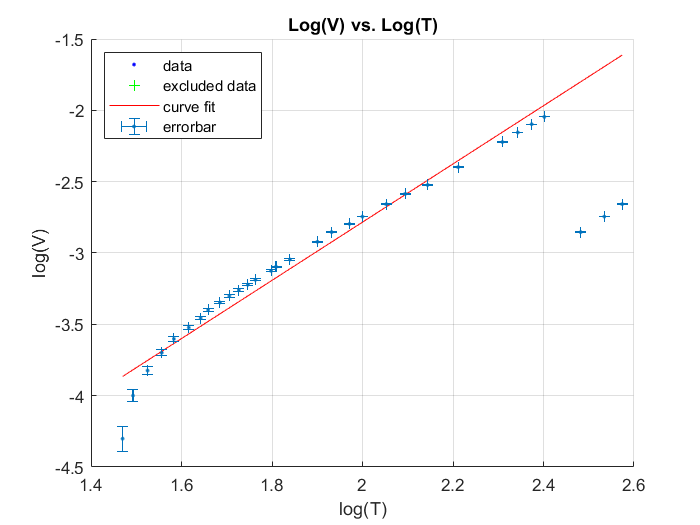

Verr=0.00001*ones(31,1);
Terr=Terr.';
Verr=Verr.';
logTerr = ((Terr./(log(10)*T)));
logVerr=((Verr./(log(10)*V)));
xpos=logTerr;
xneg=xpos;

ypos=logVerr;
yneg=ypos;

[xData, yData] = prepareCurveData( logT, logV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [29 30 31] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
h = plot( fitresult, xData, yData, excludedPoints );
errorbar(logT, logV, yneg, ypos, xneg, xpos,'.')

xlabel log(T)
ylabel log(V)
title('Log(V) vs. Log(T)')
grid on
legend({'data','excluded data','curve fit','errorbar'},'Location','northwest')
hold off

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =        2.01 \pm0.06 

       p2 =      -6.851 \pm0.156 

Goodness of fit:

  SSE: 0.318

  R-square: 0.9657

  Adjusted R-square: 0.9645

  RMSE: 0.1126

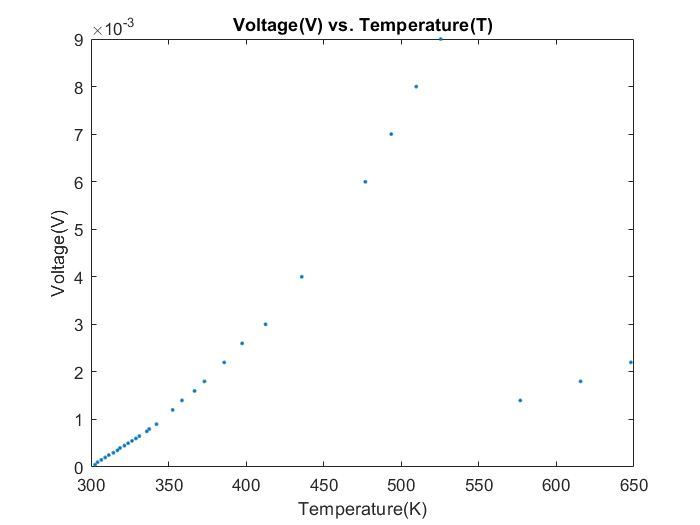

plot(T,V,'.')

title('Voltage(V) vs. Temperature(T)')
xlabel('Temperature(K)')
ylabel('Voltage(V)')